Playing Hamiltonian games with real wavefunctions

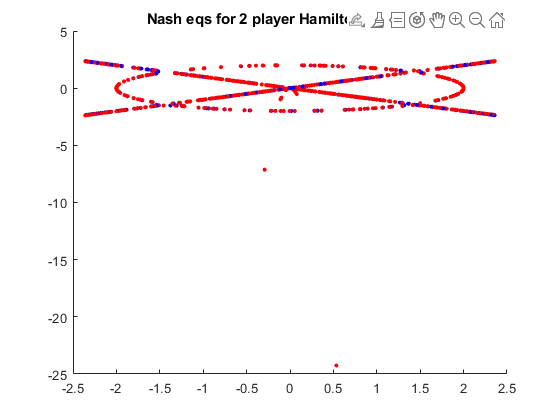

qg = struct();
figure();
hold on
N = 2; % number of players
% T = {[0,1;1,0],[0,-1i;1i,0],[1,0;0,-1]}; % generators of su(2),i.e. the Pauli matrices
GamePayoff = {randHerm(2^N,'real'),randHerm(2^N,'real')};
Hloc(:,:,1) = GamePayoff{1};
Hloc(:,:,2) = GamePayoff{2};

% storing data in struct
qg.N = N;
qg.payoff = Hloc;

Hloc(:,:,1) = PauliI(2,1,1);
Hloc(:,:,2) = PauliI(2,2,1);
Hloc(:,:,1) = diag([3,5,0,1]);
Hloc(:,:,2) = diag([3,0,5,1]);
%Hloc(:,:,1) = eye(4); Hloc(:,:,2) = eye(4);
% now plot several sets of the Nash equilibrium points
f0 = @(phi) F(phi,N,Hloc);
df0 = @(phi,h) dF(phi,N,Hloc,h);

Hloc1(:,:,1) = Hloc(:,:,1) + 0.01*randHerm(2^N,'real');
Hloc1(:,:,2) = Hloc(:,:,2);

f1 = @(phi) F(phi,N,Hloc1);
df1 = @(phi,h) dF(phi,N,Hloc1,h);

qg.f = f0;
qg.df = df0;

h = 2.2e-16;
ftol = 1e-15;
Nd = 1000;
qg.eq = zeros(4,Nd);
qg.init = zeros(4,Nd);
dp = zeros(4,Nd);
for rep = 1:Nd
    phi0 = 1-2*rand(4,1); phi0 = phi0/norm(phi0);
    qg.init(:,rep) = phi0;
    displayoption = 0;
    [phi,fval,phis,fvals,aopts] = NEsolver(phi0,f0,df0,ftol,displayoption);
    qg.eq(:,rep) = phi;
    NEaddplot(phis,0,'b');
    [phi1,fval1,phis1,fvals1,aopts1] = NEsolver(phi0,f1,df1,ftol,displayoption);
    NEaddplot(phis1,0,'r');
    dp(:,rep) = phi1-phi;
end
title('Nash eqs for 2 player Hamiltonian games')
set(gcf,'Visible','on')

% saveas(gcf,'qg_qpd.fig')
% qg.fig = 'qg_qpd.fig';

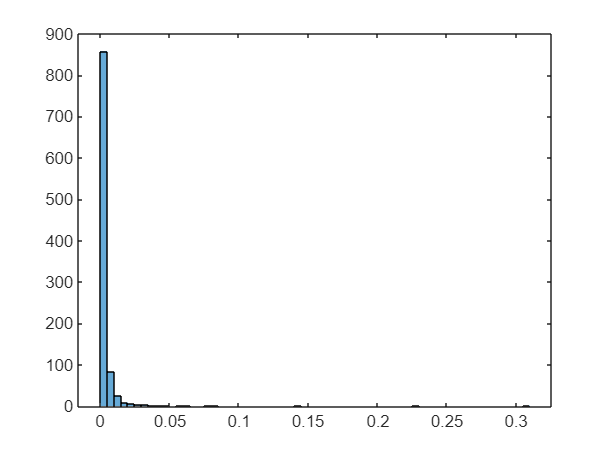

% slightly perturb away from the commuting point by adding a small, random
% perturbation matrix
figure()
ldp = sqrt(sum(dp.^2));
histogram(ldp)                                                                                   

Next is to relax the condition for $H$ to be real and symmetric to Hermiticity. 

c = 'complex';
d = 'real';
Hloc(:,:,1) = randHerm(2^N,c);
Hloc(:,:,2) = randHerm(2^N,c);

Hloc(:,:,1) = eye(4) + 0.01*randHerm(2^N,c);
Hloc(:,:,2) = eye(4) + 0.01*randHerm(2^N,c);
displayoption = 1;
flgComplex = 1;
f0 = @(phi) F(phi,N,Hloc);
df0 = @(phi,h) dF(phi,N,Hloc,h,flgComplex);
ftol = 1e-20;
phi0 = (1-2*rand(4,1)) + 1i* (1-2*rand(4,1));
phi0 = phi0/norm(phi0);
phi0_pt = phi0 + 0.4*((1-2*rand(4,1)) + 1i* (1-2*rand(4,1)));
phi0_pt = phi0_pt/norm(phi0_pt);
%[phi,fval,phis,fvals,aopts] = NEsolver(phi0,f0,df0,ftol,displayoption,flgComplex);
[phi1,fval1,phis1,fvals1,aopts1,T] = NEsolver(phi0_pt,f0,df0,ftol,displayoption,flgComplex);


iters = 1:T;
figure()
yyaxis left
plot(iters,log(aopts1(iters)))
yyaxis right
plot(iters,log(fvals1(iters)))
% hold on
% plot(iters,imag(phis(:,iters)),'-.')
% hold off

Observed that upon perturbation of the initial state gives a perturbed Nash stationary state. Till now the space of states has been $S^7$ instead of $CP^3$, where a global phase has not yet been quotiented out

format long
phi./phi1

This shows the states is indeed up to a global phase

function H = randHerm(d,F)
% create generic (nonlocal) payoff functions
% no guarantee on the normalization of eigenvalue distributions
switch F
    case 'real'
        H = rand(d);
    case 'complex'
        H = (rand(d) + 1i*rand(d))/sqrt(2);
end
H = 1/2*(H + H');
end


% the following are specific for 2 player games
function y = F(phi,N,Hloc)
    % find the sum-of-square of all constraints for a Nash stationary
    % state
    % phi: input state
    % N: number of sites
    % Hloc: the local Hamiltonian/ payoff functions
    A = zeros(3*N,1);
    for j = 1:N
        for a = 1:3
            G = fG(j,a,Hloc);
            A(3*(j-1)+a) = phi'*G*phi;
        end
    end
    y = A'*A/(phi'*phi)^2;
end

function dy = dF(phi,N,Hloc,h,flgComplex)
    % """numerically find the derivative of the sum-of-square constraint, will
    % be used in the gradient descent algorithm"""
    % phi: input state
    % N: number of sites
    % Hloc: the local Hamiltonian/ payoff functions
    % h: a small, positive number for approximating the derivative by a
    % difference
    % 
    % Set flgComplex = 1 to search over the complex wavefunctions
    if nargin < 5
        flgComplex = 0;
    end
    if flgComplex==0
        dy = zeros(length(phi),1);
        for i = 1:length(phi)
            dx = zeros(length(phi),1);
            dx(i) = h;
            dy(i) = (F(phi+dx,N,Hloc) - F(phi-dx,N,Hloc))/(2*h);
        end
    else
        % with flgComplex = 1
        dy = zeros(2*length(phi),1);
        for i = 1:2*length(phi)
            dx = zeros(2*length(phi),1);
            dx(i) = h;
            dx = dx(1:length(phi)) + 1i * dx(length(phi)+1:end);
            dy(i) = (F(phi+dx,N,Hloc) - F(phi-dx,N,Hloc))/(2*h);
        end
    end 
    % this algorithm has error of the order h^2
end

function NEaddplot(phis,flagPath,ptcol)
% The algorithm should add a plot to current figure, if there's no figure
% present, add a figure with hold on

% check whether a figure exist
if isempty(get(groot, 'Children'))
    figure;
    hold on;
    grid on;
end

% input state should be an element in S3, now stereo project to R3
% xinit = 2*phis(2,1)./(1+phis(1,1));
% yinit = 2*phis(3,1)./(1+phis(1,1));
% zinit = 2*phis(4,1)./(1+phis(1,1));
xend = 2*phis(2,end)./(1+phis(1,end));
yend = 2*phis(3,end)./(1+phis(1,end));
zend = 2*phis(4,end)./(1+phis(1,end)); 


if flagPath == 1
    x = 2*phis(2,:)./(1+phis(1,:));
    y = 2*phis(3,:)./(1+phis(1,:));
    z = 2*phis(4,:)./(1+phis(1,:)); 
    dx = diff(x);
    dy = diff(y);
    dz = diff(z);
    scatter3(x,y,z,10*ones(size(x)),'filled','Color','r');
    for i = 1:length(x)-1
        quiver3(x(i), y(i), z(i), dx(i), dy(i), dz(i), 1, 'MaxHeadSize', 0.3, 'Color', 'b');
    end
end
%scatter3(xinit,yinit,zinit,10,'r','Marker','o')
scatter3(xend,yend,zend,10,'filled',ptcol)
end

function A = C(X,Y)
A = X*Y - Y*X;
end